# 1. 개별 Lidar, 좌표 이동 없이 각각 그리기

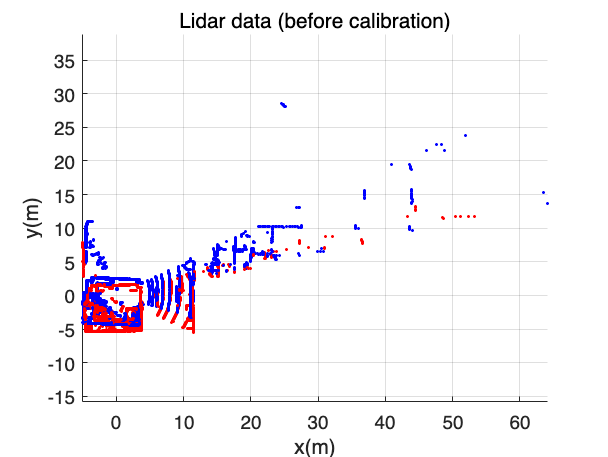

% 16 Channel : 개구각 360도
lidar_data = load('lidar_data.mat');

lidar_1 = lidar_data.lidar_1;
lidar_2 = lidar_data.lidar_2;

figure(); hold on; xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
title('Lidar data (before calibration)'); axis equal; grid on;
plot3(lidar_1(:,1),lidar_1(:,2),lidar_1(:,3),'.r','MarkerSize',5);
plot3(lidar_2(:,1),lidar_2(:,2),lidar_2(:,3),'.b','MarkerSize',5);

# 2. 3D로 그려보기 (Lidar 1)

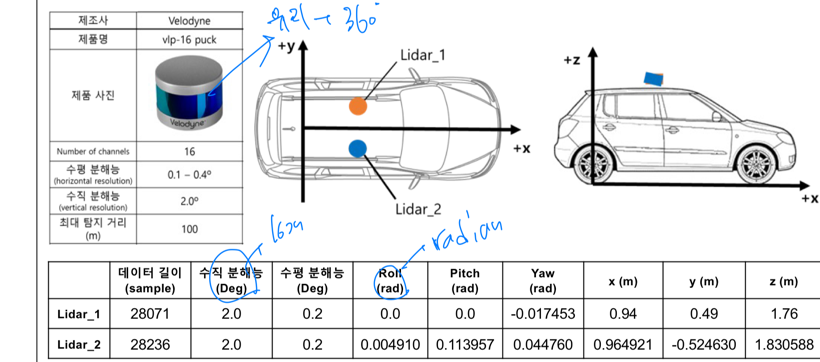

% x, y, z축 평행이동한 m
x_1 = 0.94;
y_1 = 0.49;
z_1 = 1.76;
% Roll, Pitch, Yaw 회전한 radian
roll_1= 0.0;
pitch_1 = 0.0;
yaw_1 = -0.017453; 

cos_r_1 = cos(roll_1); 
sin_r_1 = sin(roll_1); 
cos_p_1 = cos(pitch_1); 
sin_p_1 = sin(pitch_1); 
cos_y_1 = cos(yaw_1); 
sin_y_1 = sin(yaw_1);

% 두 Lidar를 정합하기 위해서 Lidar 1의 data 교정
r_matrix_1 = [
    1 0 0 0; 
    0 cos_r_1 -sin_r_1 0; 
    0 sin_r_1 cos_r_1 0;
    0 0 0 1];
    
p_matrix_1 = [
    cos_p_1 0 -sin_p_1 0;
    0 1 0 0;
    -sin_p_1 0 cos_p_1 0;
    0 0 0 1];
    
y_matrix_1 = [
    cos_y_1 sin_y_1 0 0;
    sin_y_1 cos_y_1 0 0;
    0 0 1 0;
    0 0 0 1];

tl_matrix_1 = [
    1 0 0 x_1;
    0 1 0 y_1;
    0 0 1 z_1;
    0 0 0 1]; 

tf_matrix_1 = tl_matrix_1 * y_matrix_1 * p_matrix_1 * r_matrix_1;

tf_lidar_1=[];

for i = 1:length(lidar_1)
    temp = [lidar_1(i,1); lidar_1(i,2); lidar_1(i,3); 1];
    temp_2 = tf_matrix_1 * temp;
    tf_lidar_1 = [tf_lidar_1; [temp_2(1,1) temp_2(2,1) temp_2(3,1)]];
end

# 2. 3D로 그려보기 (Lidar 2)

% x, y, z축 평행이동한 m
x_2 = 0.9649214;
y_2 = -0.52463;
z_2 = 1.8305882; 
% Roll, Pitch, Yaw 회전한 radian
roll_2 = 0.0049101; 
pitch_2 = 0.113957; 
yaw_2 = 0.0447597; 
cos_r_2 = cos(roll_2); 
sin_r_2 = sin(roll_2); 
cos_p_2 = cos(pitch_2); 
sin_p_2 = sin(pitch_2); 
cos_y_2 = cos(yaw_2); 
sin_y_2 = sin(yaw_2);

% 두 Lidar를 정합하기 위해서 Lidar 2의 data 교정
r_matrix_2 = [
    1 0 0 0; 
    0 cos_r_2 -sin_r_2 0; 
    0 sin_r_2 cos_r_2 0;
    0 0 0 1];
    
p_matrix_2 = [
    cos_p_2 0 -sin_p_2 0;
    0 1 0 0;
    -sin_p_2 0 cos_p_2 0;
    0 0 0 1];
    
y_matrix_2 = [
    cos_y_2 sin_y_2 0 0;
    sin_y_2 cos_y_2 0 0;
    0 0 1 0;
    0 0 0 1];

tl_matrix_2 = [
    1 0 0 x_2;
    0 1 0 y_2;
    0 0 1 z_2;
    0 0 0 1]; 

tf_matrix_2 = tl_matrix_2 * y_matrix_2 * p_matrix_2 * r_matrix_2;

tf_lidar_2=[];

for i = 1:length(lidar_1)
    temp = [lidar_2(i,1); lidar_2(i,2); lidar_2(i,3); 1];
    temp_2 = tf_matrix_2 * temp;
    tf_lidar_2 = [tf_lidar_2; [temp_2(1,1) temp_2(2,1) temp_2(3,1)]];
end

# 3. Car Object plotting

car_data=stlread('hyundai_i30.stl'); 
car_x=car_data.vertices(:,1)';
car_y=car_data.vertices(:,2)'; 
car_z=car_data.vertices(:,3)'; 
car=[car_x;car_y;car_z;ones(1,length(car_x))]; 
car_roll=90/180*pi; 
car_yaw=90/180*pi; 
R_car_roll=[
    1 0 0 0;
    0 cos(car_roll) -sin(car_roll) 0;
    0 sin(car_roll) cos(car_roll) 0;
    0 0 0 1];
R_car_yaw=[
    cos(car_yaw) -sin(car_yaw) 0 0;
    sin(car_yaw) cos(car_yaw) 0 0;
    0 0 1 0;
    0 0 0 1];

car_re= R_car_yaw * R_car_roll * car;
car_zdot=-min(car_re(3,:))+0.2;
y_temp=sort(car_re(2,:));
car_ydot=-y_temp(118278/2);
car_xdot=-1.8;
L_car=[
    1 0 0 car_xdot;
    0 1 0 car_ydot; 
    0 0 1 car_zdot;
    0 0 0 1]; 
car_re=L_car *car_re;

# 4. 3D map plot

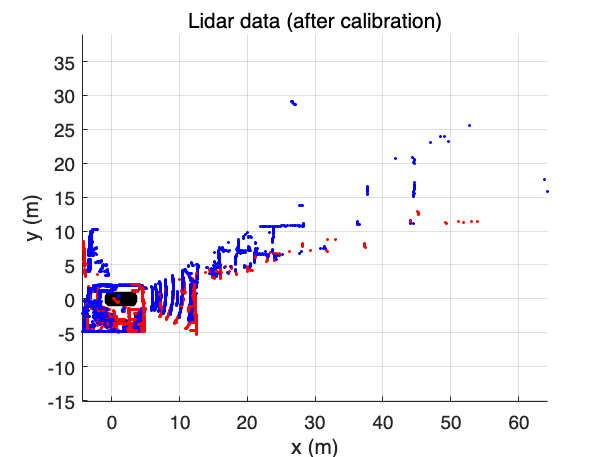

figure(); hold on; title('');
plot3(tf_lidar_1(:,1),tf_lidar_1(:,2),tf_lidar_1(:,3),'.r','MarkerSize',5);
plot3(tf_lidar_2(:,1),tf_lidar_2(:,2),tf_lidar_2(:,3),'.b','MarkerSize',5);
plot3(car_re(1,:),car_re(2,:),car_re(3,:),'k.')
title('Lidar data (after calibration)'); axis equal; grid on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');